## Matisse

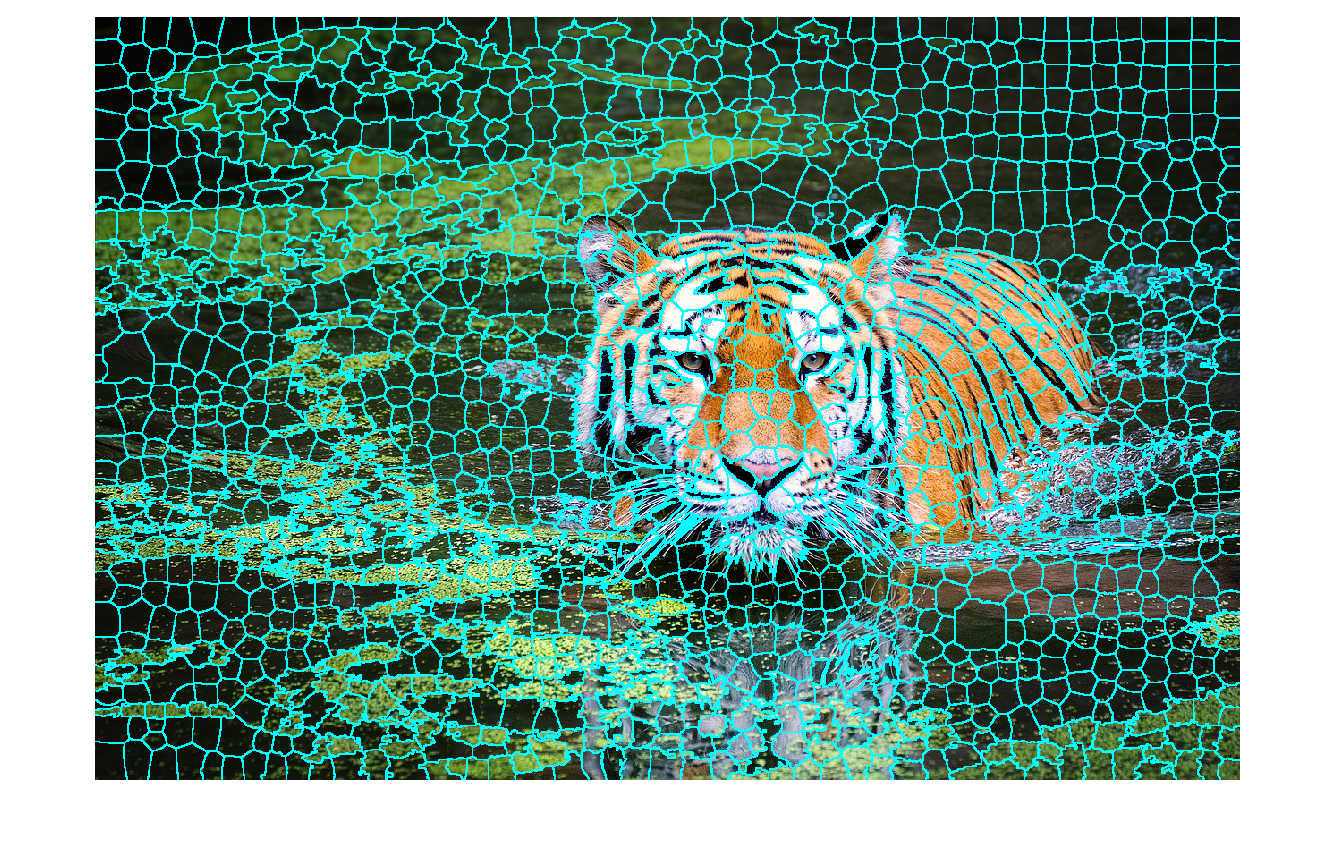

% Import input image
input = imread('project_img.jpeg');

% Specify superpixel parameters
numSuperPixels = 1500;
compactness = 15;

% Run superpixels function
[labels,n] = superpixels(input,numSuperPixels, 'Compactness', compactness);

% Show the original image with the superpixels mask overlaid
figure
mask = boundarymask(labels);
imshow(imoverlay(input, mask,'cyan'))

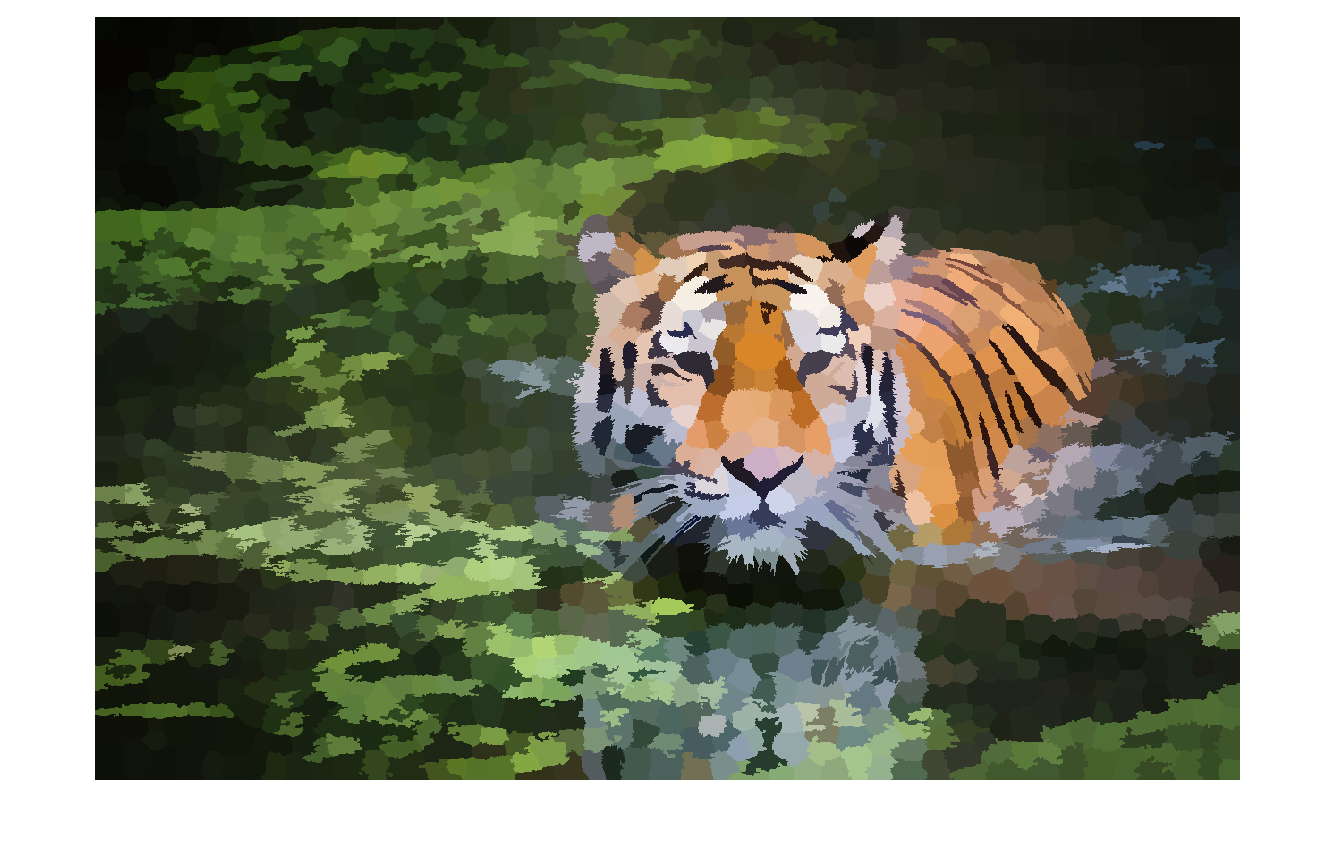

% Create an output image of the same size as the input
outputImage = zeros(size(input),'like',input);

% Iterate over each superpixel and assign the color value of the superpixel
% to be the average color of all the pixels in that region
idx = label2idx(labels);
numRows = size(input,1);
numCols = size(input,2);
for labelVal = 1:n
    redIdx = idx{labelVal};
    greenIdx = idx{labelVal}+numRows*numCols;
    blueIdx = idx{labelVal}+2*numRows*numCols;
    outputImage(redIdx) = mean(input(redIdx));
    outputImage(greenIdx) = mean(input(greenIdx));
    outputImage(blueIdx) = mean(input(blueIdx));
end    

% Define the radius of the circular structuring element
radius = 6;

% Create a circular structuring element
se = strel('disk', radius);

% Initialize the eroded image
erodedImage = uint8(zeros(size(outputImage)));

% Apply erosion on each color channel separately
for channel = 1:3
    channelImage = outputImage(:, :, channel);
    erodedChannel = imerode(channelImage, se);
    erodedImage(:, :, channel) = erodedChannel;
end

% Display superpixel output
imshow(outputImage);

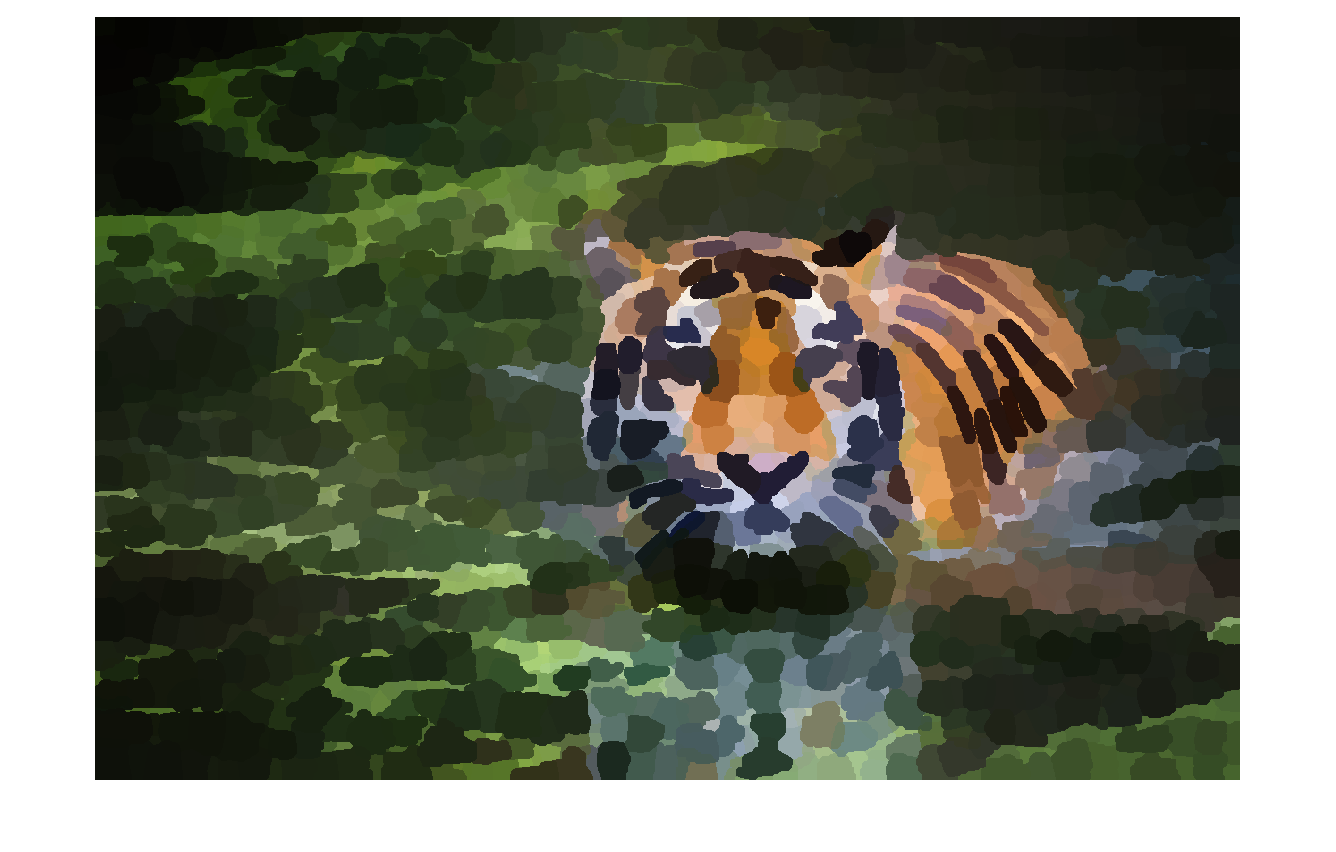

% Display the eroded image
imshow(erodedImage);

## Scratch Art

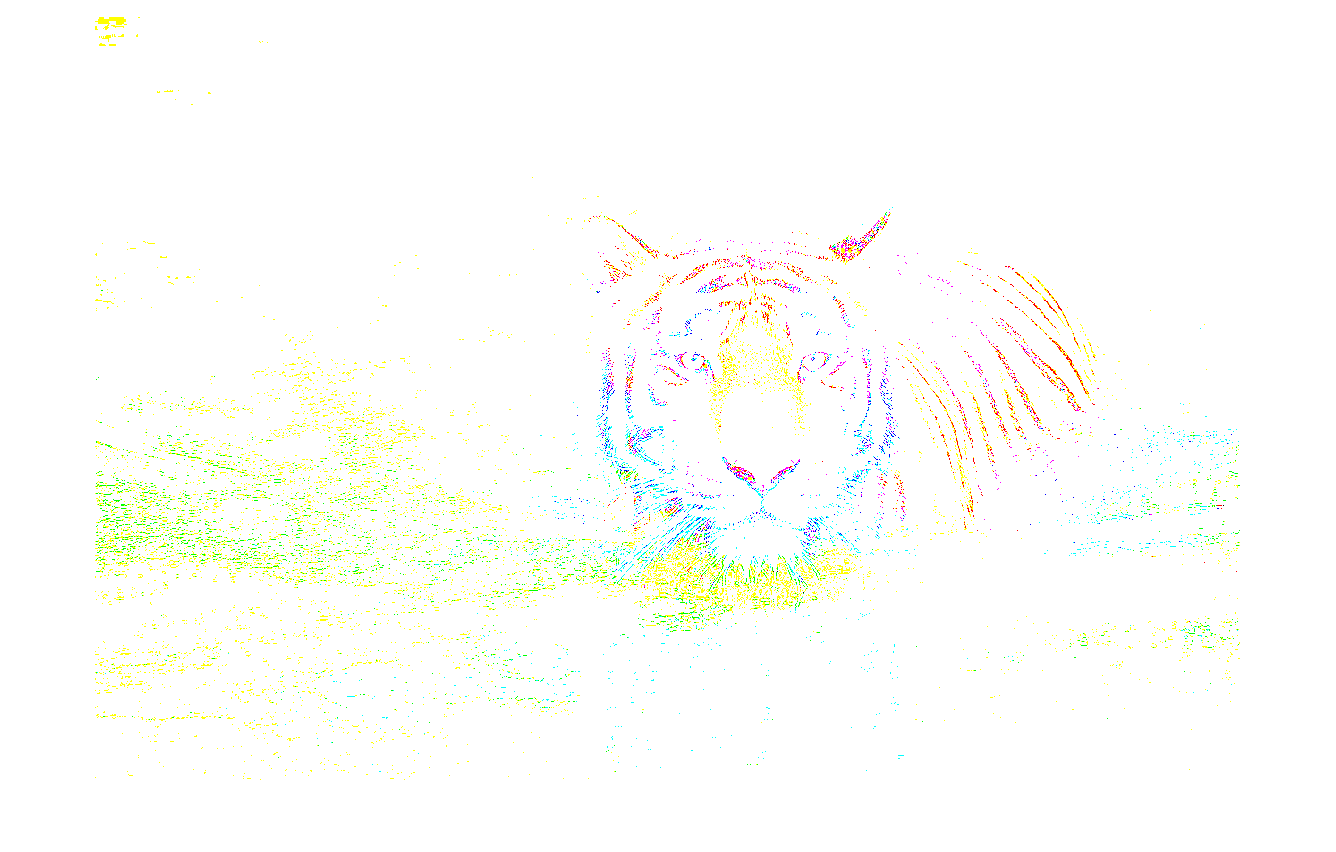

% Import input image
image = imread('project_img.jpeg');

% Specify parameters and run superpixels function
numSuperpixels = 500;
[L, numLabels] = superpixels(image, numSuperpixels);

% Set the radius of the circular shape
radius = 5;

% Iterate over each superpixel
outputImage = im2double(image);

for label = 1:numLabels
    mask = (L == label);
    
    % Find the centroid of the superpixel
    [rows, cols] = find(mask);
    centroidX = round(mean(cols));
    centroidY = round(mean(rows));
    
    % Create a circular mask for the superpixel
    superpixelMask = false(size(mask));
    [x, y] = meshgrid(1:size(mask, 2), 1:size(mask, 1));
    superpixelMask(sqrt((x-centroidX).^2 + (y-centroidY).^2) > radius) = true;
    
    % Resize the superpixel mask to match the size of the output image
    superpixelMask = imresize(superpixelMask, size(outputImage(:, :, 1)));
    
    % Apply the mask to the superpixel across each color channel
    for channel = 1:size(image, 3)
        outputImage(:, :, channel) = double(image(:, :, channel)) .* superpixelMask + outputImage(:, :, channel) .* ~superpixelMask;
    end
end

% Display the transformed image
imshow(outputImage);